# Homework 6  - Farshad Bolouri - R11630884

### Problem 1)

We wish to create a solution to decimate audio files from 48000 samples/second to 8000 samples/second, without

causing too much distortion to the frequencies that are kept.

clear
close all
[toneramp, tonerampFs] = audioread("new_toneramp.wav");
tonerampInfo = audioinfo("new_toneramp.wav")

tonerampInfo = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/new_toneramp.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 144001
             Duration: 3.0000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


[equinox, equinoxFs] = audioread("equinox-48KHz.wav");
equinoxInfo = audioinfo("equinox-48KHz.wav")

equinoxInfo = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/equinox-48KHz.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 719965
             Duration: 14.9993
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


a) Design an anti-aliasing FIR filter that you consider appropriate for this purpose.

#### *Filter Design*

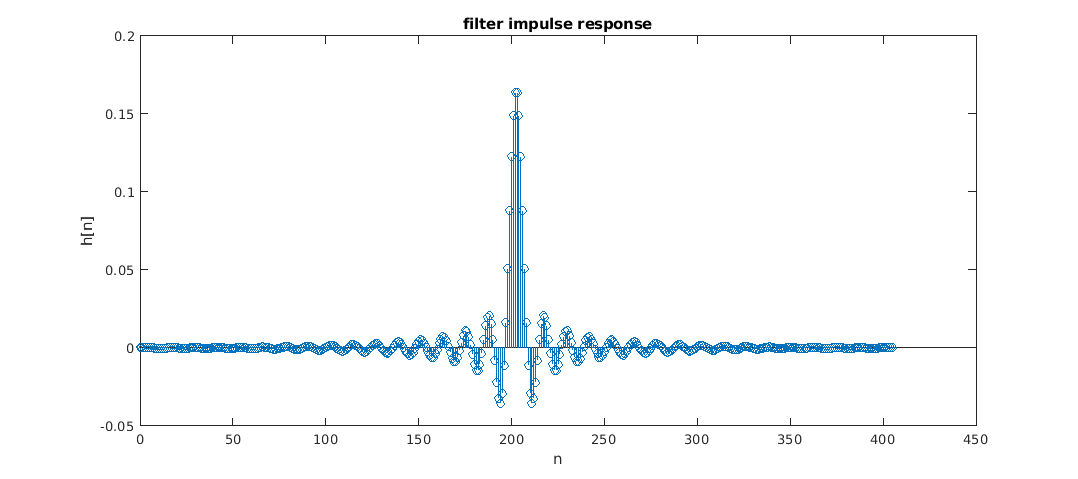

% FIR least-squares Lowpass filter designed using the FIRLS function.

% All frequency values are in Hz.
Fs = 48000;  % Sampling Frequency

N     = 405;   % Order
Fpass = 3800;  % Passband Frequency
Fstop = 4200;  % Stopband Frequency
Wpass = 1;     % Passband Weight
Wstop = 90;    % Stopband Weight

% Calculate the coefficients using the FIRLS function.
h = firls(N, [0 Fpass Fstop Fs/2]/(Fs/2), [1 1 0 0], [Wpass Wstop]);
lsFilter = dfilt.dffir(h);

% graph filter impulse response
graph = figure;
stem(0:length(h)-1,h)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

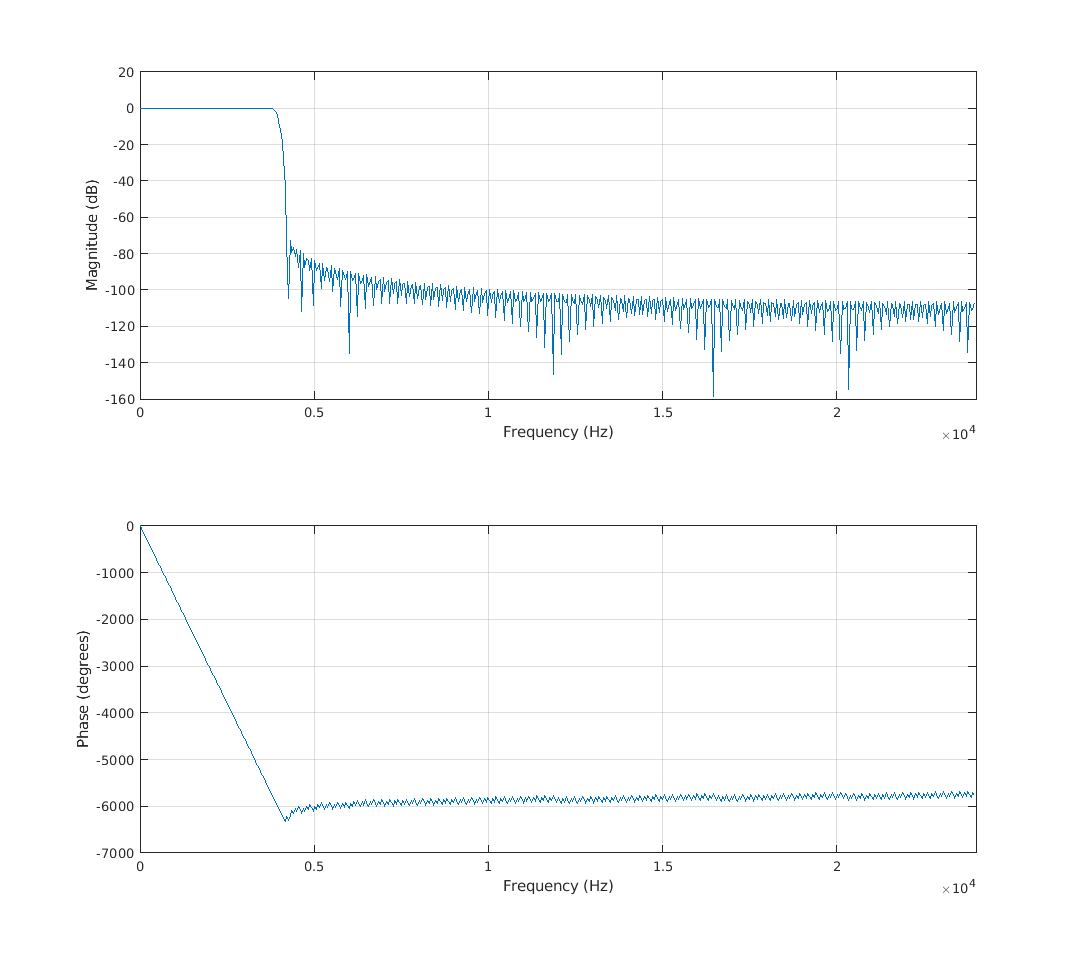

% graph filter frequency response
graph = figure;
freqz(h,1,[],equinoxFs)
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

*I chose my passband ripple to be 1 dB because I didn't want too much fluctuations in the frequencies that I am trying to keep.*

*I put the stopband attenuation to 60 dB  as I found to be enough to remove the frequecies that I don't want.*

*My *$f_s$* is at 48000 Hz as this is the sampling frequency of my original signal.*

*I put my *$f_c$* to 4000 Hz and the way I calculated this *$f_c$* was : *$\frac{\frac{f_s }{2}}{M}=\frac{\frac{48000}{2}\;\textrm{Hz}}{6}=4000\;\textrm{Hz}$*.*

*As for the choice of my Lowpass Filter design method, I tried designing the same filter with ****Equiripple, Kaiser Window****, and**** Least Squares.***

***Least Squares: ****For this filter, as it doesn't provide the "Minimum Order" option, I had to play with different orders and weights until I was able to meet the conditions of my filter. At the end, I was able to design a filter with ****Order = 405****.*

***Kaiser Window:**** With the "Minimum Order" condition, I got a filter of ****Order = 436.***

***Equiripple:**** With the "Minimum Order" condition, I got a filter of order = 236****. ****But the filter didn't exactly meet the conditions that I needed and also it included many ripples in the passband. So after playing with the orders and weights, I designed a filter with ****Order = 325**** which could match up against the previous two filter with still maintaining much less complexity than them.*

*Here's a comparison between the frequency response of the three filters.*

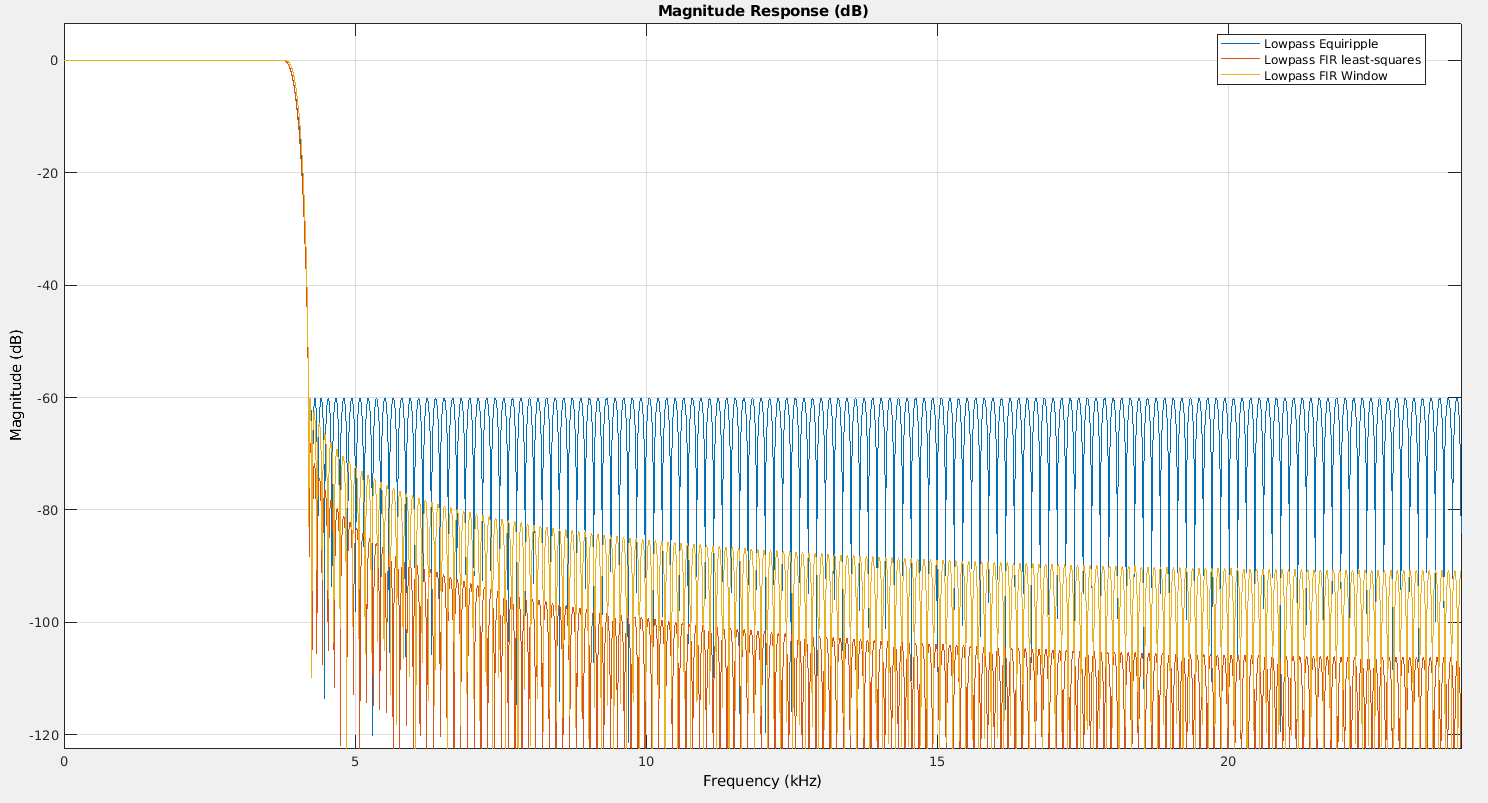

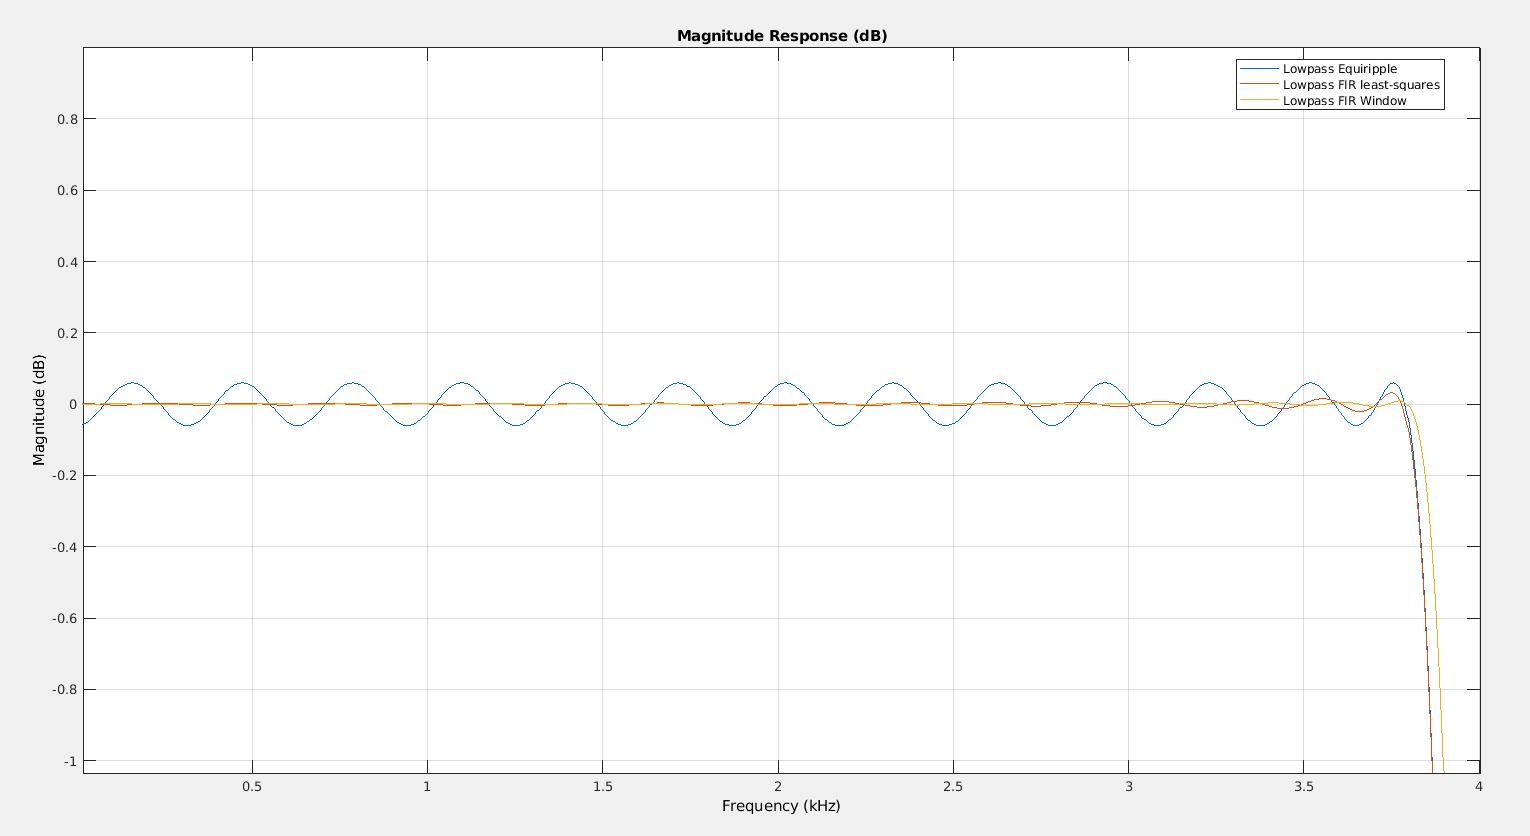

*I did a visual and auditory analysis of the results of the three filters:*

*The ****Kaiser Window ****and ****Least Squares ****filter provided the same results while you could still see an hear the reipples in the result of ****Equiripple ****filter. And since the ****Least Squares ****filter had less complexity (smaller order) than the ****Kaiser Window ****filter, I chose the ****Least Square ****design* *method as my final filter.*

#### Applying the Filter

b) Apply your filter to audio from toneramp.wav (still at 48000 samples/second)

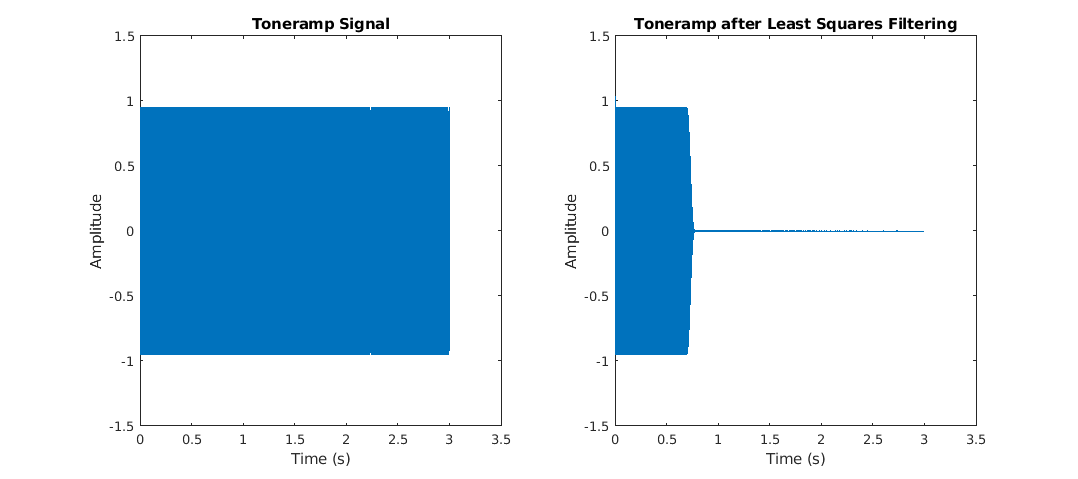

timeToneramp = linspace(0, tonerampInfo.Duration, tonerampInfo.TotalSamples);

filteredToneramp = filter(lsFilter, toneramp);

% Taking care of clipping with scaling to [-1, 1]
filteredTonerampWav = rescale(filteredToneramp, -1, 1);
audiowrite('filteredToneramp.wav', filteredTonerampWav, tonerampFs);

graph = figure;
subplot(121)
plot(timeToneramp, toneramp)
title('Toneramp Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-1.5 1.50])

subplot(122)
plot(timeToneramp, filteredToneramp)
title('Toneramp after Least Squares Filtering')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-1.5 1.50])

*You can see the attenutaton after filtering. There's a smooth transition to attenuated signal as soon as the signal reaches around our cut-off frequency around 4000Hz (between 0.5 - 1 second).*

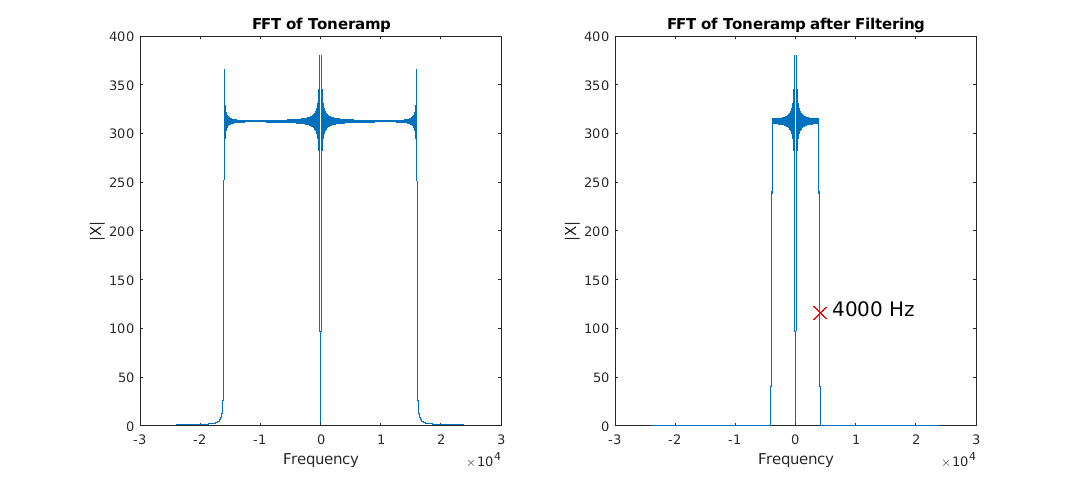

tonerampFFT = abs(fftshift(fft(toneramp)));                  % Zero-Centered FFT
tonerampF = (-tonerampInfo.TotalSamples/2:tonerampInfo.TotalSamples/2-1)...
    /tonerampInfo.TotalSamples*tonerampFs;                   % Zero-Centered Frequency Range

filteredTonerampFFT = abs(fftshift(fft(filteredToneramp)));  % Zero-Centered FFT

graph = figure;
subplot(121)
plot(tonerampF, tonerampFFT)
title('FFT of Toneramp');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,2)
plot(tonerampF, filteredTonerampFFT)
hold on
title('FFT of Toneramp after Filtering');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
text(6000,120,'4000 Hz', 'FontSize',15)
plot(4000.47,115.794,'rx','LineWidth', 2, 'MarkerSize',12)
hold off

*Here in the frequency dmoain you can see the attenuation of the Frequencies above 4000 Hz even better.*

#### Decimation

c) Implement the rest of the decimation process in MATLAB

M = tonerampFs/8000;                                            % Decimating Factor
decimatedToneramp = filteredToneramp(1:M:end);

audiowrite("decimatedToneramp.wav", decimatedToneramp, 8000);
decimatedTonerampInfo = audioinfo("decimatedToneramp.wav")

decimatedTonerampInfo = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/decimatedToneramp.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 24001
             Duration: 3.0001
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


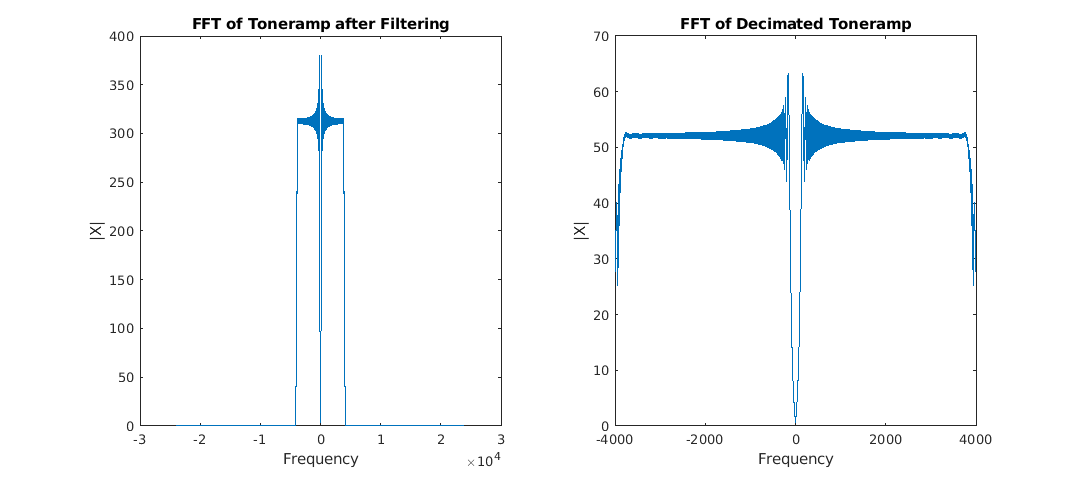

decimatedTonerampFFT = abs(fftshift(fft(decimatedToneramp)));   % Zero-Centered FFT
decimatedTonerampF = (-decimatedTonerampInfo.TotalSamples/2:...
    decimatedTonerampInfo.TotalSamples/2-1)...
    /decimatedTonerampInfo.TotalSamples*tonerampFs/M;           % Zero-Centered Frequency Range                     % Zero-Centered Frequency Range

graph = figure;
subplot(122)
plot(decimatedTonerampF, decimatedTonerampFFT)
title('FFT of Decimated Toneramp');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,1)
plot(tonerampF, filteredTonerampFFT)
title('FFT of Toneramp after Filtering');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

*You can see how the values of |X| has gotten smaller because we reduced the sampling rate and also how there's no gap between 4000 to 24000 hz range. *

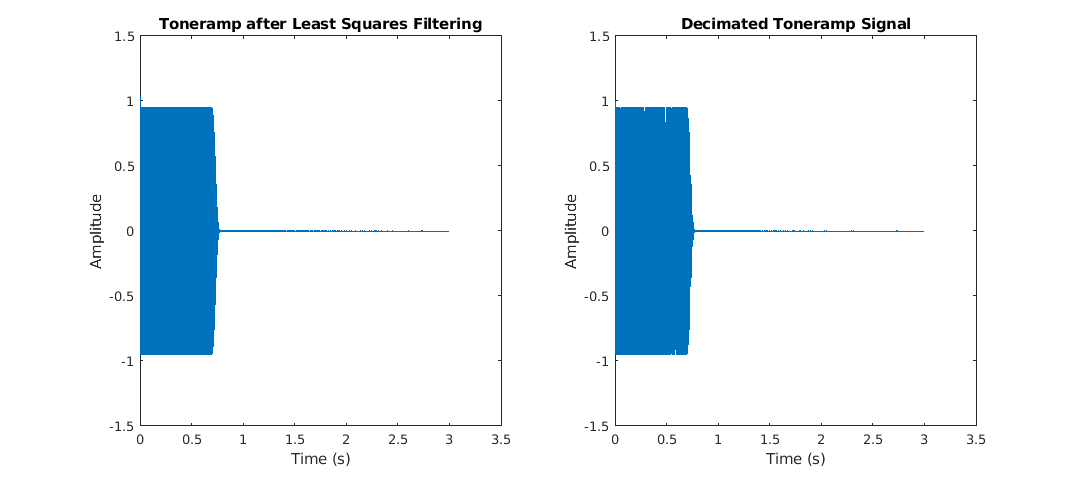

timeDecimatedToneramp = linspace(0, decimatedTonerampInfo.Duration...
    , decimatedTonerampInfo.TotalSamples);

graph = figure;
subplot(122)
plot(timeDecimatedToneramp, decimatedToneramp)
title('Decimated Toneramp Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-1.5 1.50])

subplot(121)
plot(timeToneramp, filteredToneramp)
title('Toneramp after Least Squares Filtering')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-1.5 1.50])

*After doing a visual and auditory analysis of the above signals, you can't really tell the difference between the two. However you can see a couple of small gaps in the decimated signal around 0.5s point which makes sense as we have reduced the sampling rate by a factor of 6.*

d) Apply your decimation to the audio file equinox-48kHz.wav.

timeEquinox = linspace(0, equinoxInfo.Duration, equinoxInfo.TotalSamples);

filteredEquinox = filter(lsFilter, equinox);

equinoxFFT = abs(fftshift(fft(equinox)));                       % Zero-Centered FFT
equinoxF = (-equinoxInfo.TotalSamples/2:...
    equinoxInfo.TotalSamples/2-1)...
    /equinoxInfo.TotalSamples*equinoxFs;                        % Zero-Centered Frequency Range 

M = equinoxFs/8000;                                             % Decimating Factor
decimatedEquinox = filteredEquinox(1:M:end);

audiowrite("decimatedEquinox.wav", decimatedEquinox, 8000);
decimatedEquinoxInfo = audioinfo("decimatedEquinox.wav")

decimatedEquinoxInfo = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/decimatedEquinox.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 119995
             Duration: 14.9994
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


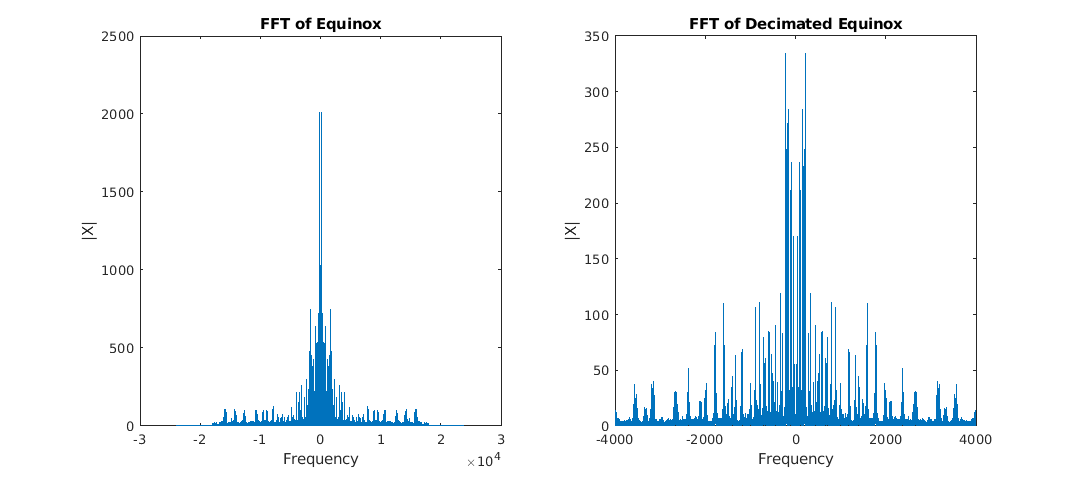

decimatedEquinoxFFT = abs(fftshift(fft(decimatedEquinox)));     % Zero-Centered FFT
decimatedEquinoxF = (-decimatedEquinoxInfo.TotalSamples/2:...
    decimatedEquinoxInfo.TotalSamples/2-1)...
    /decimatedEquinoxInfo.TotalSamples*equinoxFs/6;             % Zero-Centered Frequency Range                     % Zero-Centered Frequency Range

graph = figure;
subplot(122)
plot(decimatedEquinoxF, decimatedEquinoxFFT)
title('FFT of Decimated Equinox');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,1)
plot(equinoxF, equinoxFFT)
title('FFT of Equinox');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

*You can see how the values of |X| has gotten smaller because we reduced the sampling rate and also how our frequency range is between -4000 to 4000 Hz rather than -24000 to 24000 Hz but the shape of the signal still looks the same.*

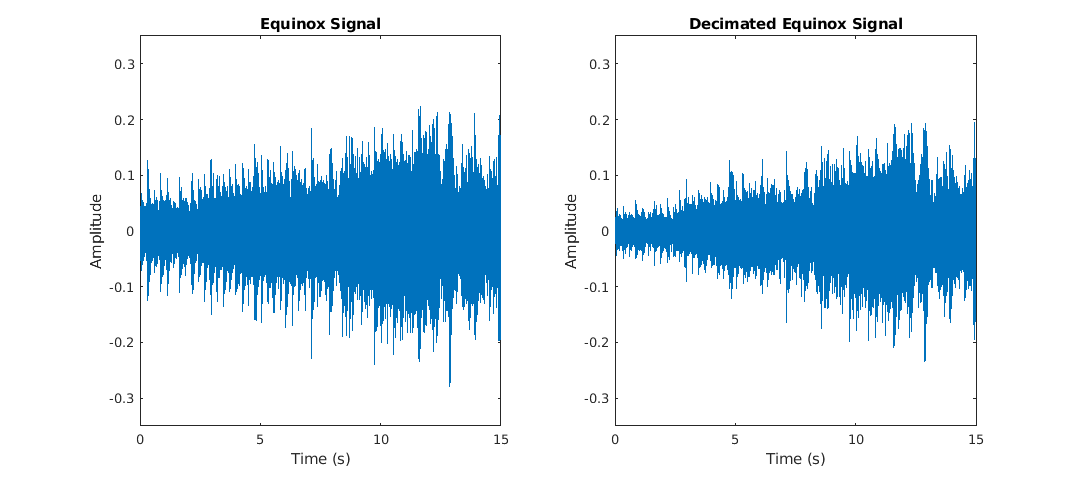

timeDecimatedEquinox = linspace(0, decimatedEquinoxInfo.Duration...
    , decimatedEquinoxInfo.TotalSamples);

graph = figure;
subplot(122)
plot(timeDecimatedEquinox, decimatedEquinox)
title('Decimated Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-0.35 0.35])

subplot(121)
plot(timeEquinox, equinox)
title('Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-0.35 0.35])

*After listenning to the two audio files I could definitely see the difference between the two. As we are atennuating high frequency components, you can tell how you don't hear the loud bells anymore and they sound quiter/damper.*

### Problem 2)

We wish to create a solution to interpolate audio files from 8000 samples/second to 48000 samples/second, without

causing too much distortion to the signal present.

a) Implement the sample rate increase in MATLAB (by zero insertion)

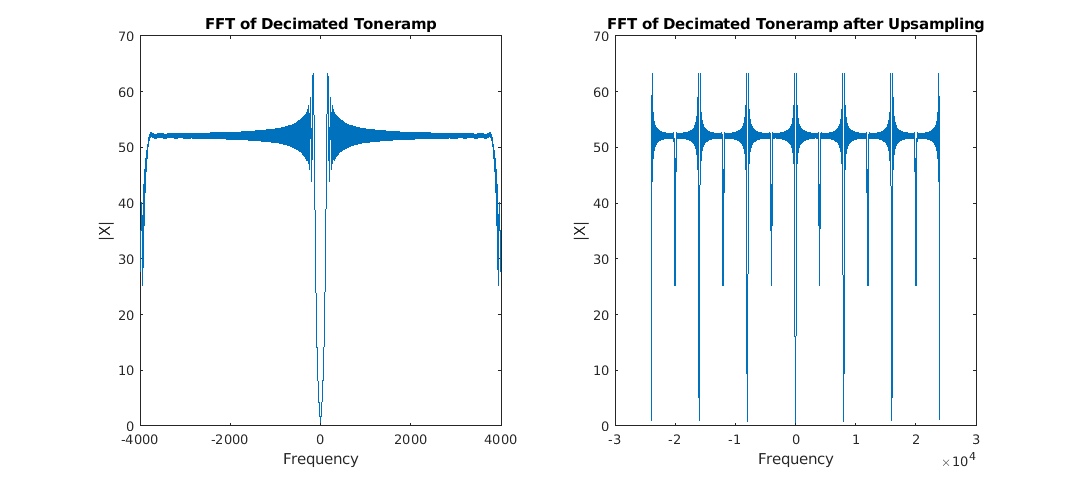

L = 48000/decimatedTonerampInfo.SampleRate;

upsampledToneramp(1:L:L*decimatedTonerampInfo.TotalSamples) = decimatedToneramp;

upsampledTonerampFFT = abs(fftshift(fft(upsampledToneramp)));   % Zero-Centered FFT
upsampledTonerampF = (-length(upsampledToneramp)/2:...
    length(upsampledToneramp)/2-1)/length(upsampledToneramp)...
    *decimatedTonerampInfo.SampleRate*L;                        % Zero-Centered Frequency Range 

graph = figure;
subplot(121)
plot(decimatedTonerampF, decimatedTonerampFFT)
title('FFT of Decimated Toneramp');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,2)
plot(upsampledTonerampF, upsampledTonerampFFT)
title('FFT of Decimated Toneramp after Upsampling');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

*By inserting zeros we are simply increasing the sampling rate, and that's why the frequency range increased to -24000 to 24000 Hz. You can see how after the zero-insertion, the original spectrum (image of spectrum) between -4000 to 4000 Hz starts getting repeated 6 times from -24000 to 24000 Hz.  *

*The reason why this happens involves recalling how the DFT of several periods of a periodic time signal is a discrete Fourier series (DFS). That is, a DFS containing non-zero-valued spectral samples separated by zero-valued spectral samples. Again, as it can be seen , we have priodic images of or original FFT in the new spectrum; the inverse DFT of several periods of a periodic images in the spectrum results in a time sequence containing non-zero-valued time samples separated by zero-valued time samples.*

b) Design an FIR image-rejection filter that you consider appropriate for this purpose.

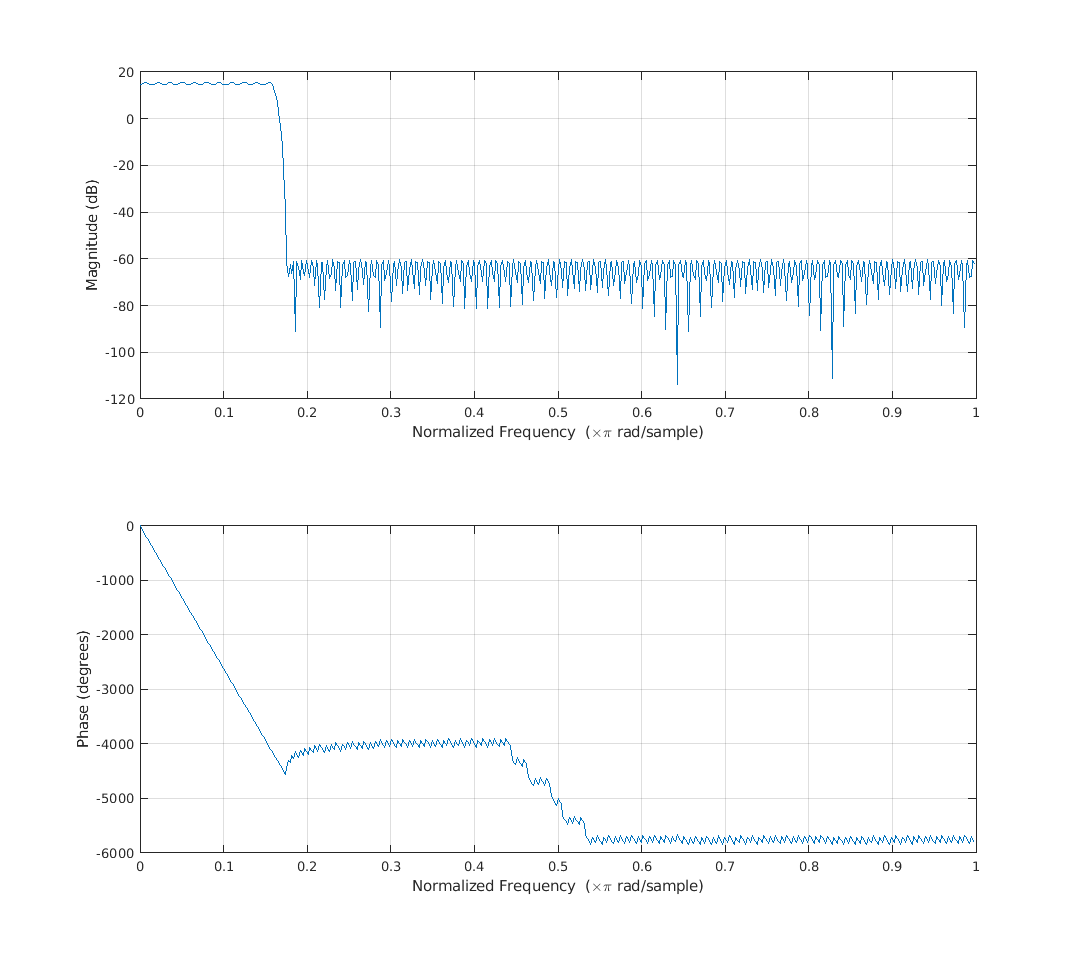

load('EqCoeff.mat')
load('EqObject.mat')

graph = figure;
freqz(EqCoeff,1);
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

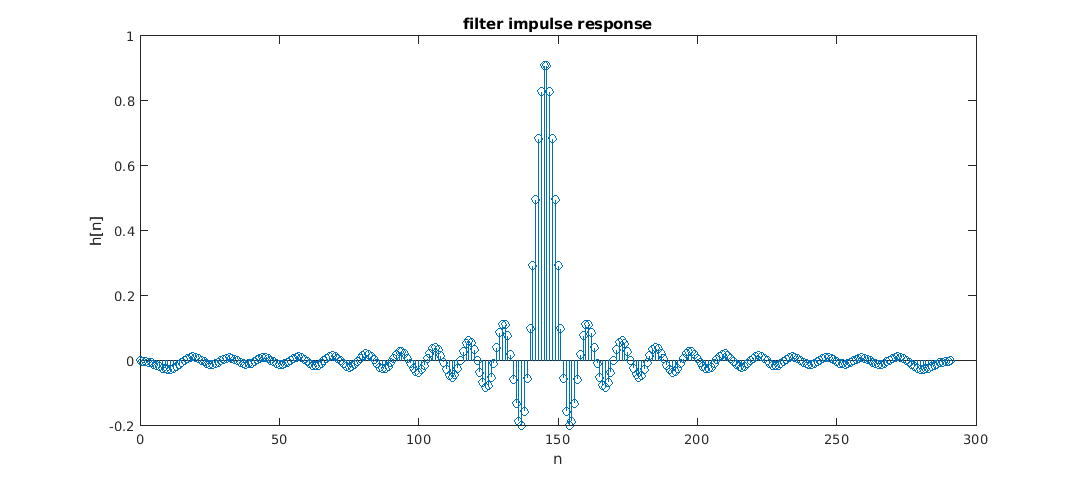

% graph filter impulse response
graph = figure;
stem(0:length(EqCoeff)-1,EqCoeff)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

*I am trying to remove the spectrum's image repetitions as shown in the last section caused by the zero-insertions. The repetitions started outside the -4000 to 4000 Hz therefore I put my *$f_c$= 4000 Hz.

*I put my *$f_s$* at 48000 Hz as this is my desired sampling frequency of the signal after interpolation. *$4000\cdot L=48000\;\textrm{Hz}$

*I chose my passband ripple to be 1 dB because I didn't want too much fluctuations in the frequencies that I am trying to keep.*

*I put the stopband attenuation to 60 dB  as I found to be enough to remove the frequecies that I don't want.*

*For my design method, I again went with a Lowpass Equiripple filter. This question requires us to design a filter with a minimum number of coefficients. In the previous problem we discovered that Equiripple definitely gives us the filter with the least number of coefficients.*

*Even though I couldn't exactly use the minimum condition option as it was intended (because I needed to add a Gain) but it definitely helped to design the filter with the least number of coeffeicients. ****Order = 291.***

#### *Interpolation*

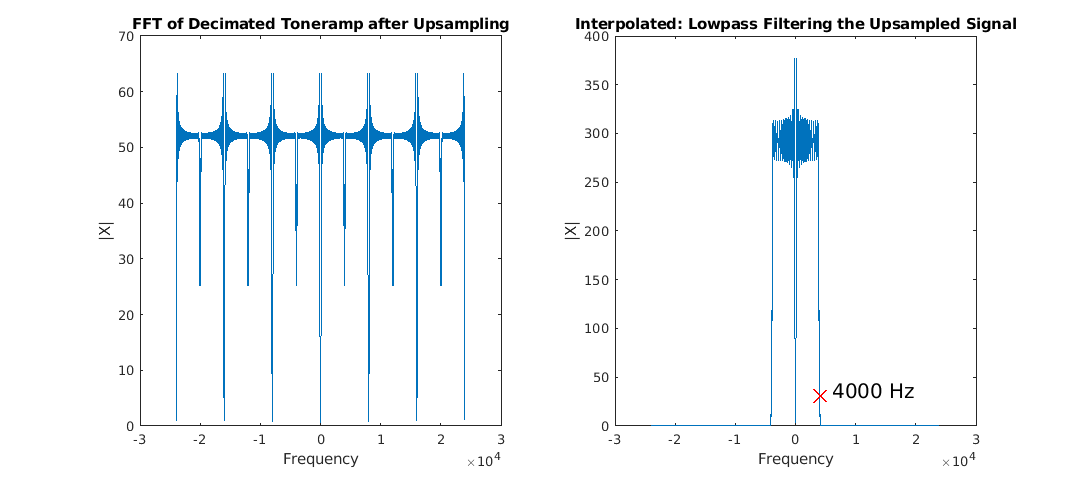

interpolatedToneramp = filter(Eq, upsampledToneramp);

audiowrite("interpolatedToneramp.wav", interpolatedToneramp, decimatedTonerampInfo.SampleRate*L);

interpolatedTonerampFFT = abs(fftshift(fft(interpolatedToneramp)));   % Zero-Centered FFT
interpolatedTonerampF = (-length(interpolatedToneramp)/2:...
    length(interpolatedToneramp)/2-1)/length(interpolatedToneramp)...
    *decimatedTonerampInfo.SampleRate*L;                              % Zero-Centered Frequency Range 

graph = figure;
subplot(122)
plot(interpolatedTonerampF, interpolatedTonerampFFT)
title('Interpolated: Lowpass Filtering the Upsampled Signal');
ylabel('|X|')
xlabel('Frequency');
hold on
text(6000,36,'4000 Hz', 'FontSize',15)
plot(4000.14,30.0944,'rx','LineWidth', 2, 'MarkerSize',12)
hold off
subplot(1,2,1)
plot(upsampledTonerampF, upsampledTonerampFFT)
title('FFT of Decimated Toneramp after Upsampling');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

*You can see how all the image repetitions are gone from the spectrum after Lowpass filtering the upsampled signal. This is because our *$f_c$= 4000 Hz and all the repetitions are happeing exactly outside the -4000 to 4000 Hz range.

interpolatedTonerampInfo = audioinfo("interpolatedToneramp.wav")    

interpolatedTonerampInfo = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/interpolatedToneramp.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 144001
             Duration: 3.0000
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


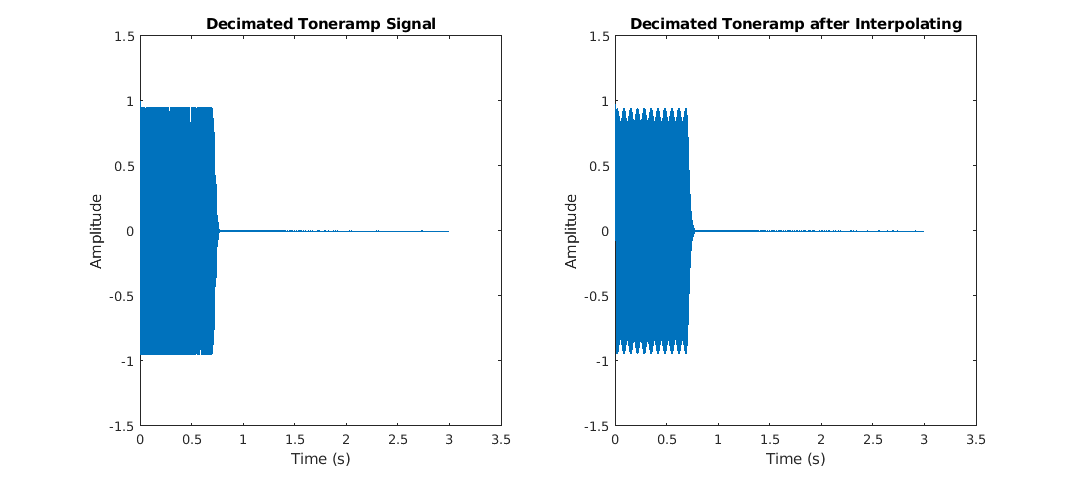

timeInterpolatedToneramp = linspace(0, interpolatedTonerampInfo.Duration...
    , interpolatedTonerampInfo.TotalSamples);

graph = figure;
subplot(121)
plot(timeDecimatedToneramp, decimatedToneramp)
title('Decimated Toneramp Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-1.5 1.50])

subplot(122)
plot(timeInterpolatedToneramp, interpolatedToneramp)
title('Decimated Toneramp after Interpolating')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-1.5 1.50])

*You can see how both are 3 seconds in duratioin which correct. And also both have the same amplitude of around 0.95. But you can see the effects (the ripples) of the Equripple filter in the interpolated signal. *

*However after doing an auditory inspection of the results, I found the two signals to sound almost identical so I am satisfied with the results.*

c) Apply your interpolation solution to the audio file from problem 1, part d)

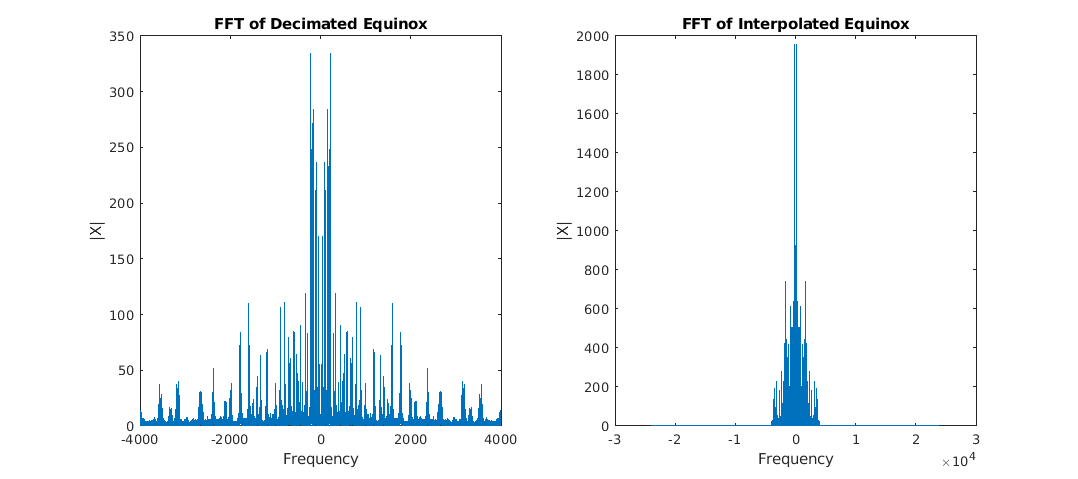

upsampledEquinox(1:L:L*decimatedEquinoxInfo.TotalSamples) = decimatedEquinox;
interpolatedEquinox = filter(Eq, upsampledEquinox);

interpolatedEquinoxFFT = abs(fftshift(fft(interpolatedEquinox)));   % Zero-Centered FFT
interpolatedEquinoxF = (-length(interpolatedEquinox)/2:...
    length(interpolatedEquinox)/2-1)/length(interpolatedEquinox)...
    *decimatedEquinoxInfo.SampleRate*L;                             % Zero-Centered Frequency Range 

audiowrite("interpolatedEquinox.wav", interpolatedEquinox, L*decimatedEquinoxInfo.SampleRate);

graph = figure;
subplot(121)
plot(decimatedEquinoxF, decimatedEquinoxFFT)
title('FFT of Decimated Equinox');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,2)
plot(interpolatedEquinoxF, interpolatedEquinoxFFT)
title('FFT of Interpolated Equinox');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

interpolatedEquinoxInfo = audioinfo("interpolatedEquinox.wav")

interpolatedEquinoxInfo = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/interpolatedEquinox.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 719965
             Duration: 14.9993
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


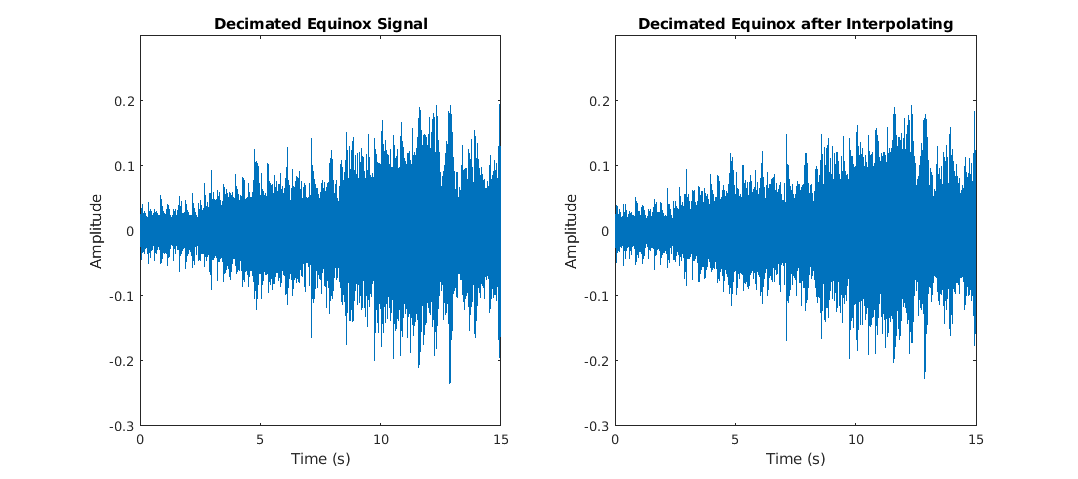

timeInterpolatedEquinox = linspace(0, interpolatedEquinoxInfo.Duration,...
    interpolatedEquinoxInfo.TotalSamples);

graph = figure;
subplot(121)
plot(timeDecimatedEquinox, decimatedEquinox)
title('Decimated Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-0.3 0.3])

subplot(122)
plot(timeInterpolatedEquinox, interpolatedEquinox)
title('Decimated Equinox after Interpolating')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-0.3 0.3])

*After doing an auditory and visual inspection, not only the signals look the same, they also exactly sound the same.*

*You can see how in the frequency domain, the shape of the spectrum look the same but just in a new range of values: -24000 to 24000 Hz.*

### Problem 3)

We wish to create a solution that can split audio files at 48000 samples/second, into two audio files, each at 24000

samples/second. The first file should contain the lower half of the representable frequencies, and the second file the

upper half of the frequencies.

a) Design a solution to extract the lower-frequency band (up to 12 kHz), decimate to 24000 samples/second, and

save it to a wav-file

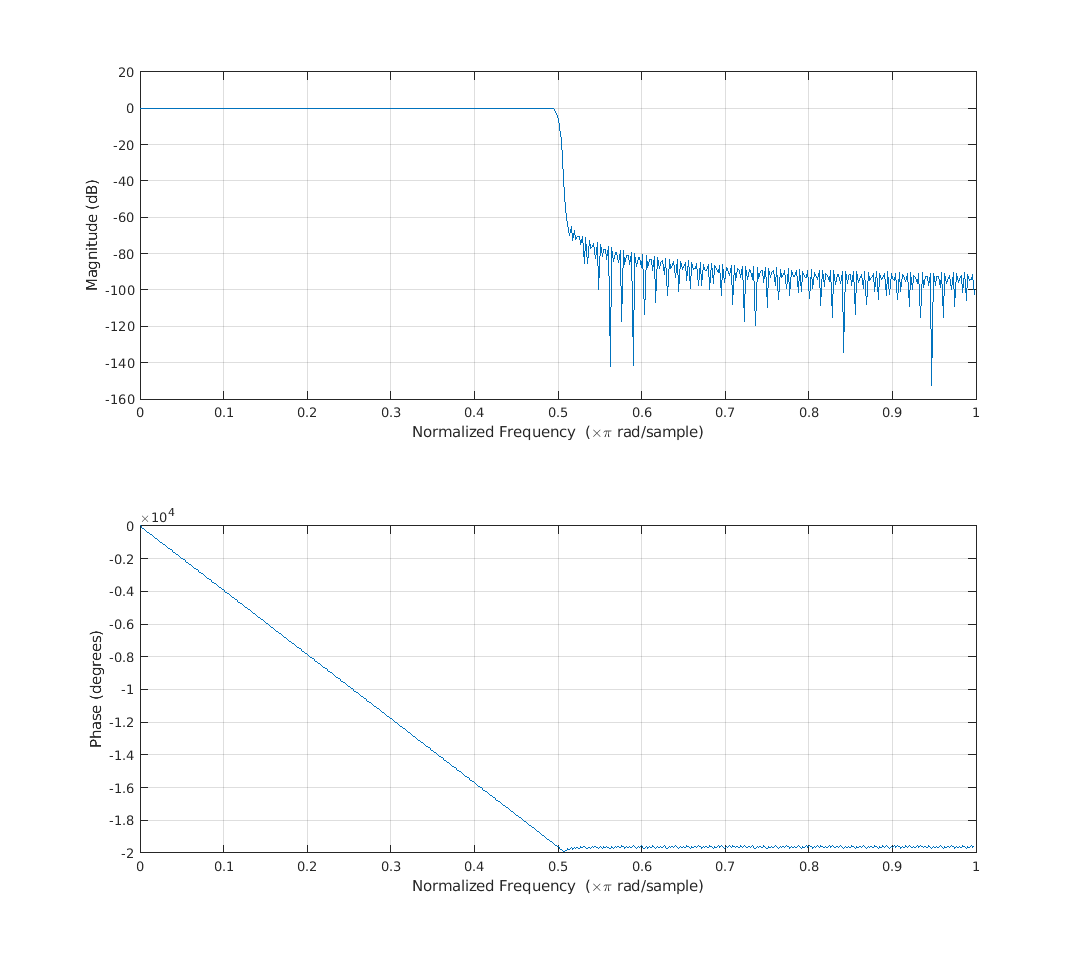

% FIR Window Lowpass filter designed using the FIR1 function.

% All frequency values are in Hz.
Fs = 48000;  % Sampling Frequency

Fpass = 11800;           % Passband Frequency
Fstop = 12200;           % Stopband Frequency
Dpass = 0.057501127785;  % Passband Ripple
Dstop = 0.001;           % Stopband Attenuation
flag  = 'scale';         % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fpass Fstop]/(Fs/2), [1 0], [Dstop Dpass]);

% Calculate the coefficients using the FIR1 function.
hKW  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
kaiserFilter = dfilt.dffir(hKW);

graph = figure;
freqz(hKW,1);
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

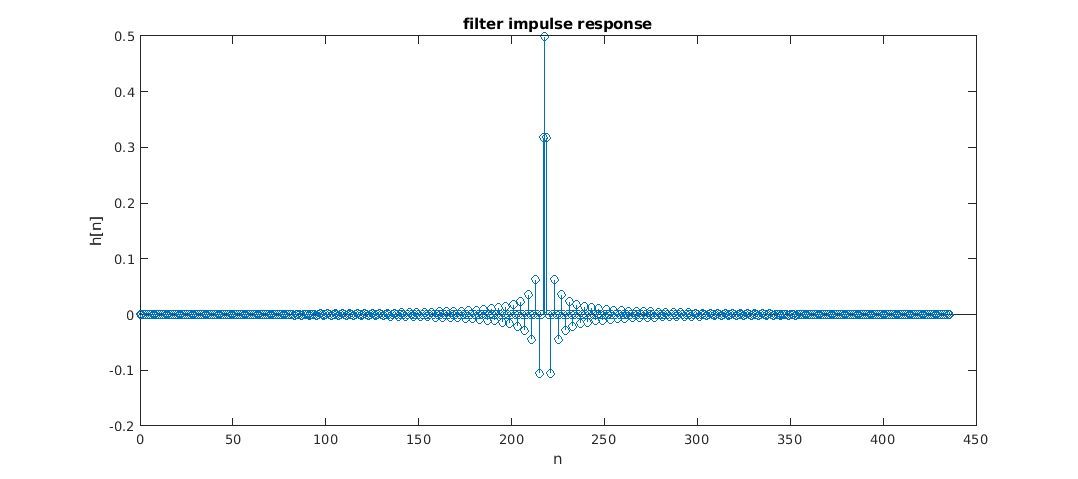

% graph filter impulse response
graph = figure;
stem(0:length(hKW)-1,hKW)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

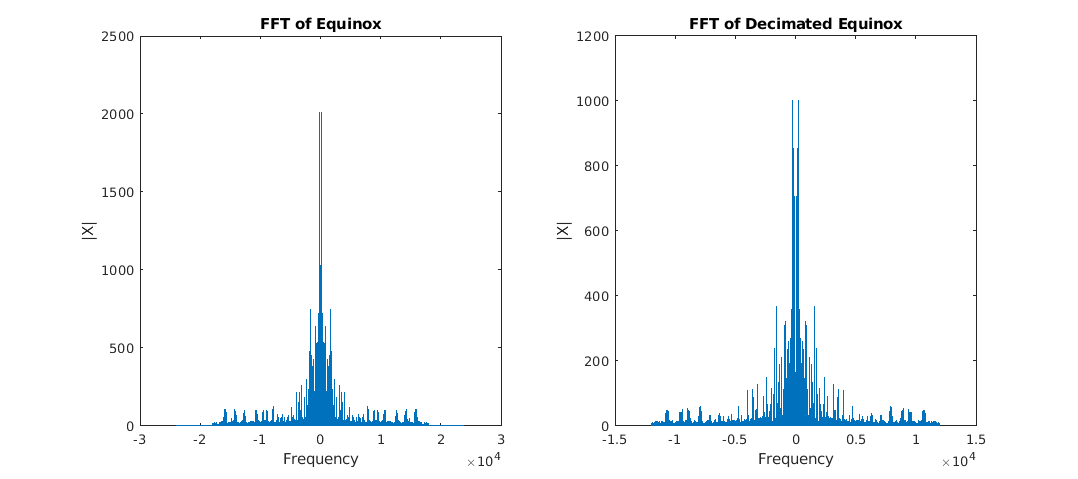

filteredEquinox_2 = filter(kaiserFilter, equinox);

M = equinoxFs/(equinoxFs/2);                                     % Decimating Factor
decimatedEquinox_2 = filteredEquinox_2(1:M:end);

audiowrite("decimatedEquinox_2.wav", decimatedEquinox_2, equinoxFs/2);

decimatedEquinoxFFT_2 = abs(fftshift(fft(decimatedEquinox_2)));     % Zero-Centered FFT
decimatedEquinoxF_2 = (-length(decimatedEquinox_2)/2:...
    length(decimatedEquinox_2)/2-1)...
    /length(decimatedEquinox_2)*equinoxFs/M;             % Zero-Centered Frequency Range                     % Zero-Centered Frequency Range

graph = figure;
subplot(122)
plot(decimatedEquinoxF_2, decimatedEquinoxFFT_2)
title('FFT of Decimated Equinox');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,1)
plot(equinoxF, equinoxFFT)
title('FFT of Equinox');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

*You can see how the frequency range has changed from [-24000  24000 Hz] to [-12000 12000 Hz] which represents the lower frequency band of the signal.*

decimatedEquinoxInfo_2 = audioinfo("decimatedEquinox_2.wav")

decimatedEquinoxInfo_2 = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/decimatedEquinox_2.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 359983
             Duration: 14.9993
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


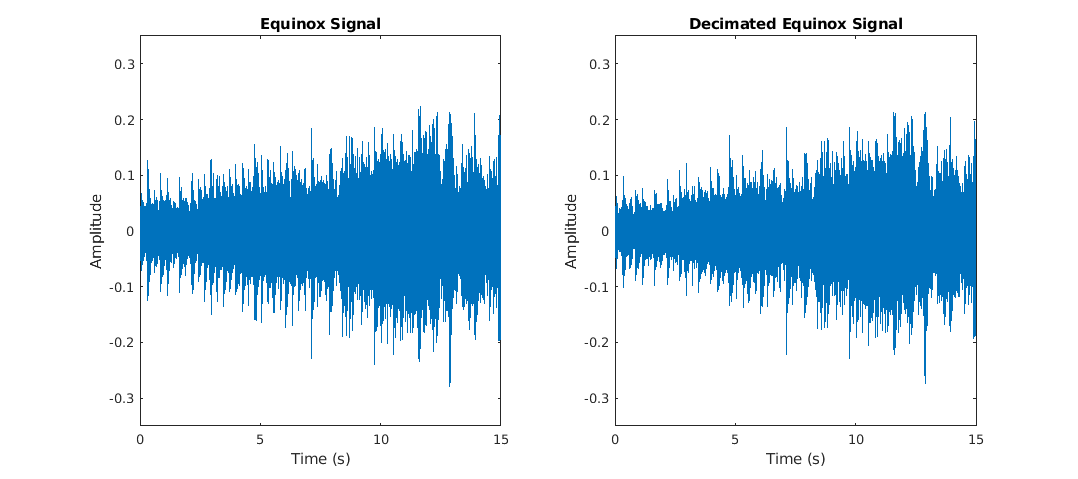

timeDecimatedEquinox_2= linspace(0, decimatedEquinoxInfo_2.Duration,...
    decimatedEquinoxInfo_2.TotalSamples);

graph = figure;
subplot(122)
plot(timeDecimatedEquinox_2, decimatedEquinox_2)
title('Decimated Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-0.35 0.35])

subplot(121)
plot(timeEquinox, equinox)
title('Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-0.35 0.35])

*The two signals sound pretty much the same however the decimated signal sounds a bit damper. Which makes as we are removing the higher frequency compoenents.*

b) Design a solution to extract the upper-frequency band (from 12kHz onward), decimate to 24000

samples/second, and save it to a wav-file

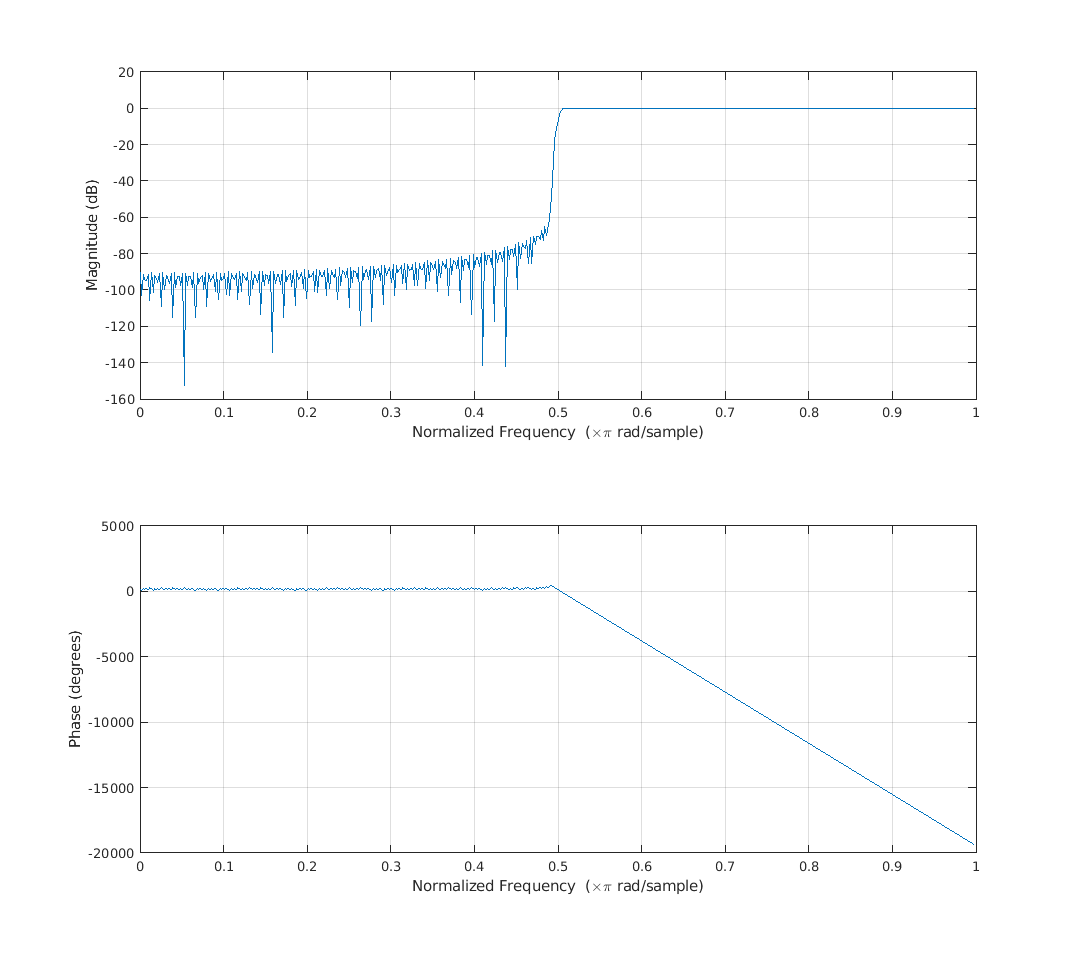

% FIR Window Highpass filter designed using the FIR1 function.

% All frequency values are in Hz.
Fs = 48000;  % Sampling Frequency

Fstop = 11800;           % Stopband Frequency
Fpass = 12200;           % Passband Frequency
Dstop = 0.001;           % Stopband Attenuation
Dpass = 0.057501127785;  % Passband Ripple
flag  = 'scale';         % Sampling Flag

% Calculate the order from the parameters using KAISERORD.
[N,Wn,BETA,TYPE] = kaiserord([Fstop Fpass]/(Fs/2), [0 1], [Dpass Dstop]);

% Calculate the coefficients using the FIR1 function.
hKW2  = fir1(N, Wn, TYPE, kaiser(N+1, BETA), flag);
kaiserFilter_2 = dfilt.dffir(hKW2);

graph = figure;
freqz(hKW2,1);
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

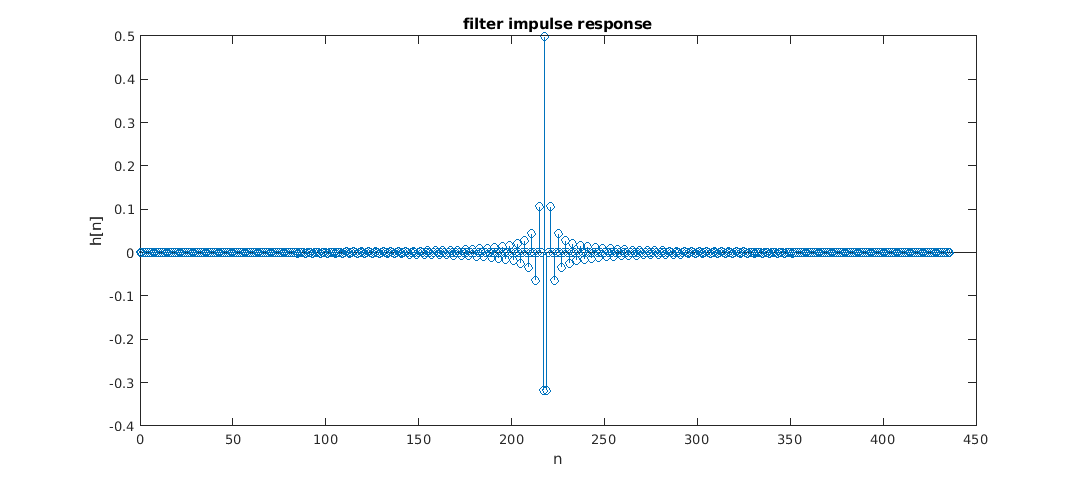

% graph filter impulse response
graph = figure;
stem(0:length(hKW2)-1,hKW2)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

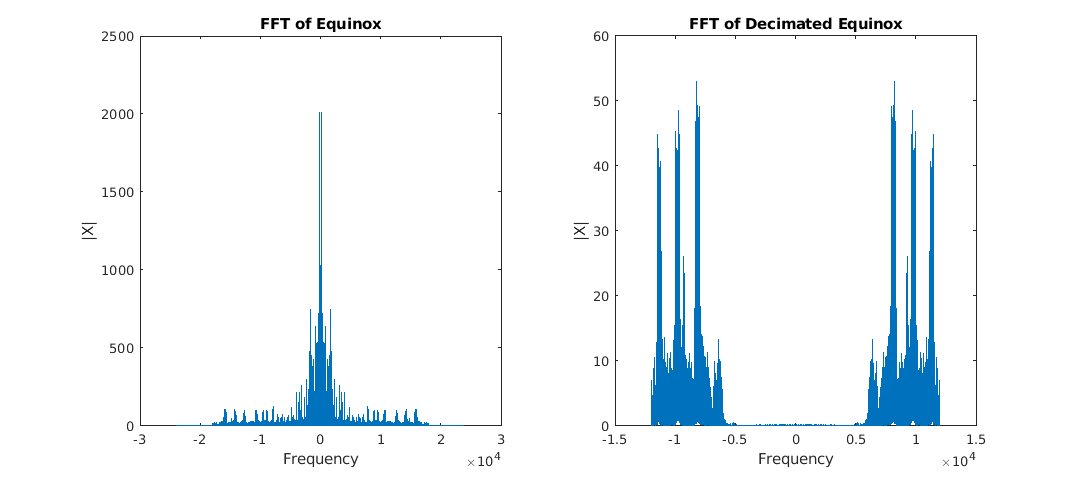

filteredEquinox_3 = filter(kaiserFilter_2, equinox);

decimatedEquinox_3 = filteredEquinox_3(1:M:end);

audiowrite("decimatedEquinox_3.wav", decimatedEquinox_3, equinoxFs/2);

decimatedEquinoxFFT_3 = abs(fftshift(fft(decimatedEquinox_3)));     % Zero-Centered FFT
decimatedEquinoxF_3 = (-length(decimatedEquinox_3)/2:...
    length(decimatedEquinox_3)/2-1)...
    /length(decimatedEquinox_3)*equinoxFs/M;             % Zero-Centered Frequency Range                     % Zero-Centered Frequency Range

graph = figure;
subplot(122)
plot(decimatedEquinoxF_3, decimatedEquinoxFFT_3)
title('FFT of Decimated Equinox');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,1)
plot(equinoxF, equinoxFFT)
title('FFT of Equinox');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

*You can see how the frequency range has again changed from [-24000  24000 Hz] to [-12000 12000 Hz] which in this case is representing the higher frequency band of the signal and that's why you are seeing the gap in the middle of our FFT.*

decimatedEquinoxInfo_3 = audioinfo("decimatedEquinox_3.wav")

decimatedEquinoxInfo_3 = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/decimatedEquinox_3.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 359983
             Duration: 14.9993
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


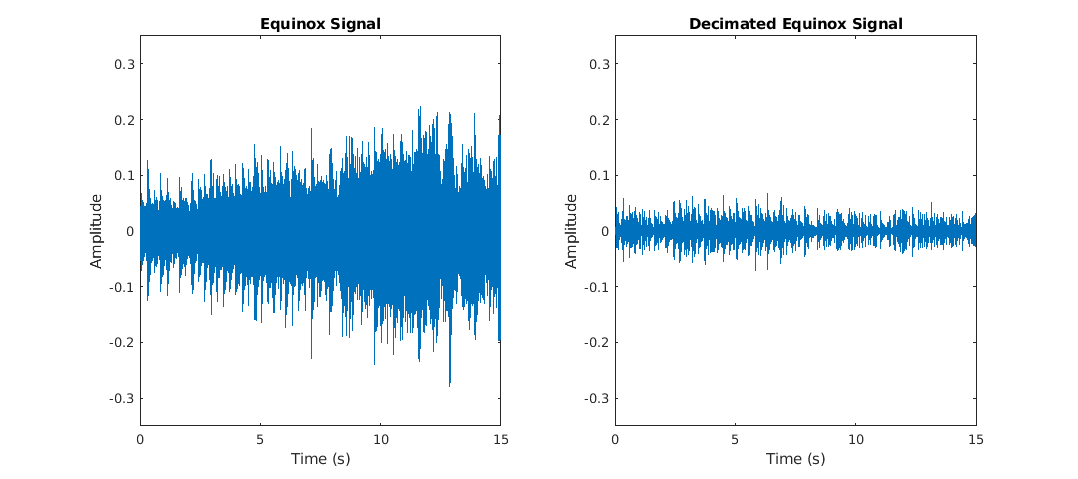

timeDecimatedEquinox_3= linspace(0, decimatedEquinoxInfo_3.Duration,...
    decimatedEquinoxInfo_3.TotalSamples);

graph = figure;
subplot(122)
plot(timeDecimatedEquinox_3, decimatedEquinox_3)
title('Decimated Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-0.35 0.35])

subplot(121)
plot(timeEquinox, equinox)
title('Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-0.35 0.35])

*Now here, after the decimation you can only hear the sharp bell and ring sounds which makes sense as we are only passing the high-frequency components. *

### Problem 4)

For the filter you designed in problem 1, create a MATLAB program that implements it in an efficient way using

polyphase filters. Verify the correctness of your implementation by comparing the output signal to the one from

problem 1.

#### *Toneramp*

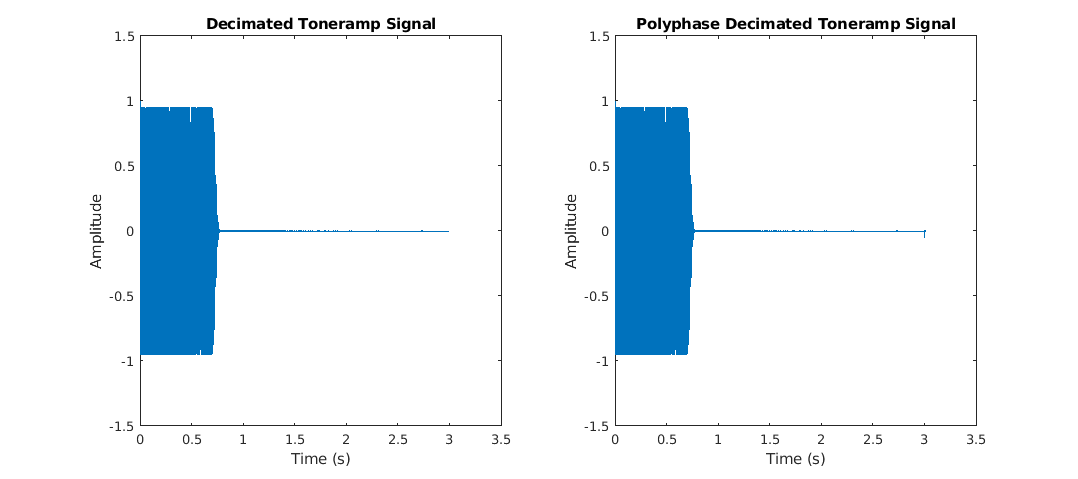

M = tonerampFs/8000;                                            % Decimating Factor
toneramp_R = toneramp';
decimatedToneramp_2 = conv(h(1:M:end),toneramp_R(1:M:end));

for ii = 2:M
    decimatedToneramp_polyphase = conv(h(ii:M:end),[0 toneramp_R(M+2-ii:M:end)]);
    
    if length(decimatedToneramp_polyphase)>length(decimatedToneramp_2)
        decimatedToneramp_2(end+1:length(decimatedToneramp_polyphase)) = 0;
    elseif length(decimatedToneramp_polyphase)<length(decimatedToneramp_2)
        decimatedToneramp_polyphase(end+1:length(decimatedToneramp_2)) = 0;
    end
    decimatedToneramp_2 = decimatedToneramp_2 + decimatedToneramp_polyphase;
   
end

timeDecimatedToneramp_2 = linspace(0, 3.0085, length(decimatedToneramp_2));

graph = figure;
subplot(121)
plot(timeDecimatedToneramp, decimatedToneramp)
title('Decimated Toneramp Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-1.5 1.50])   

subplot(122)
plot(timeDecimatedToneramp_2, decimatedToneramp_2)
title('Polyphase Decimated Toneramp Signal')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-1.5 1.50])

*After an visual and auditory inspection I couldn't tell any difference between the two signals. Which makes sense as the Poluphase implementation is just supposed to be a more efficient implementation the previous method.*

*But to make sure, lets look at the ****Mean-Squared Error ****between the two signals:*

immse(decimatedToneramp_2(1:length(decimatedToneramp))', decimatedToneramp)

ans = 4.3461e-32

*Looking at the answer once more shows that the two signals are basically identitical.*

*Let's apply yhe polyphase filter to the ****Equinox ****signal.*

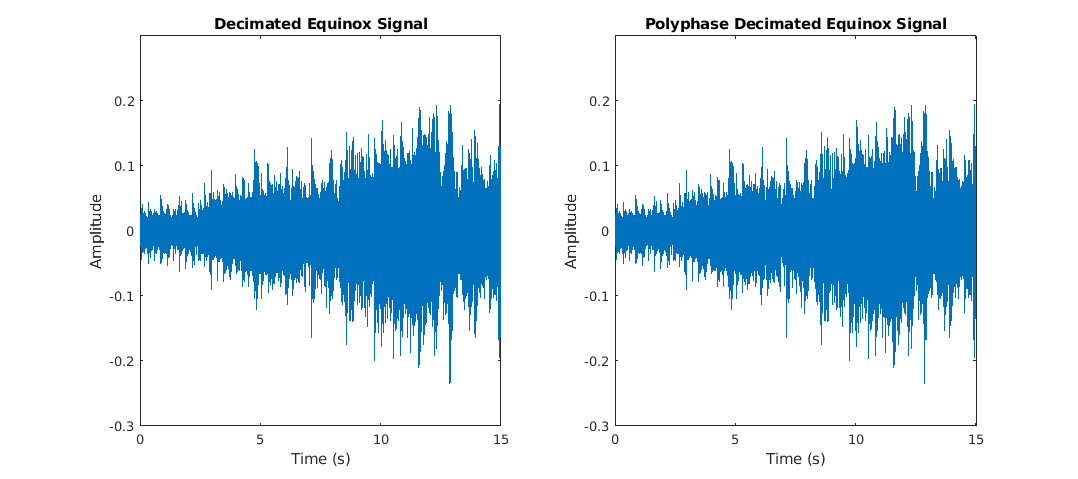

equinox_R = equinox';
decimatedEquinox_4 = conv(h(1:M:end),equinox_R(1:M:end));

for ii = 2:M
    decimatedEquinox_polyphase = conv(h(ii:M:end),[0 equinox_R(M+2-ii:M:end)]);
    
    if length(decimatedEquinox_polyphase)>length(decimatedEquinox_4)
        decimatedToneramp_2(end+1:length(decimatedEquinox_polyphase)) = 0;
    elseif length(decimatedEquinox_polyphase)<length(decimatedEquinox_4)
        decimatedEquinox_polyphase(end+1:length(decimatedEquinox_4)) = 0;
    end
    decimatedEquinox_4 = decimatedEquinox_4 + decimatedEquinox_polyphase;
   
end

timeDecimatedEquinox_4 = linspace(0, 15.0077, length(decimatedEquinox_4));

graph = figure;
subplot(121)
plot(timeDecimatedEquinox, decimatedEquinox)
title('Decimated Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-0.3 0.3])   

subplot(122)
plot(timeDecimatedEquinox_4, decimatedEquinox_4)
title('Polyphase Decimated Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-0.3 0.3])

*The results are same as before.*

### Problem 5)

We wish to invert the process done in problem 3. We want to combine the audio contained in two separate 24 kHz

audio files, each one corresponding to a separate band, into a single 48 kHz audio file.

#### *Lower-band File *

decimatedEquinoxInfo_2

decimatedEquinoxInfo_2 = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/decimatedEquinox_2.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 359983
             Duration: 14.9993
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


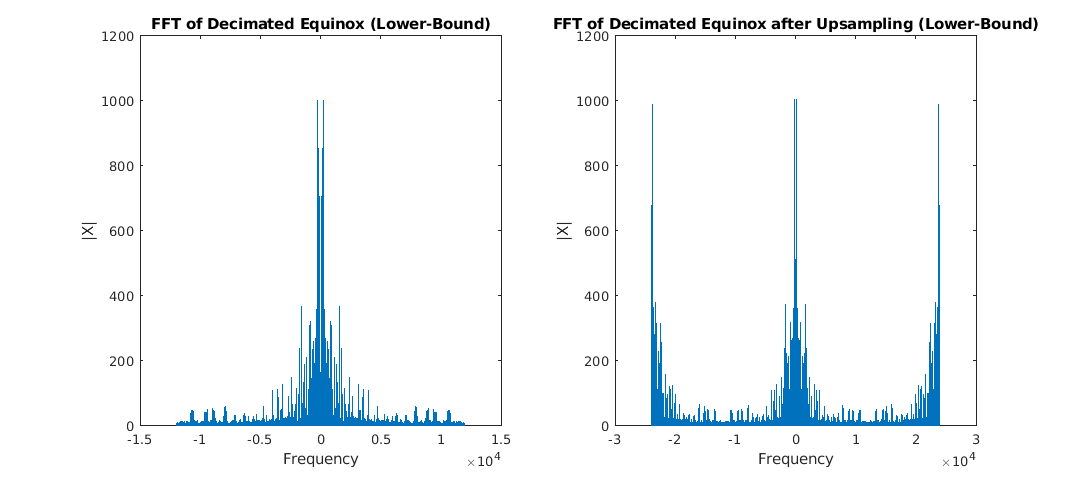

L = 48000/decimatedEquinoxInfo_2.SampleRate;

upsampledEquinox_2(1:L:L*decimatedEquinoxInfo_2.TotalSamples) = decimatedEquinox_2;

upsampledEquinoxFFT_2 = abs(fftshift(fft(upsampledEquinox_2)));     % Zero-Centered FFT
upsampledEquinoxF_2 = (-length(upsampledEquinox_2)/2:...
    length(upsampledEquinox_2)/2-1)/length(upsampledEquinox_2)...
    *decimatedEquinoxInfo_2.SampleRate*L;                           % Zero-Centered Frequency Range 

graph = figure;
subplot(121)
plot(decimatedEquinoxF_2, decimatedEquinoxFFT_2)
title('FFT of Decimated Equinox (Lower-Bound)');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,2)
plot(upsampledEquinoxF_2, upsampledEquinoxFFT_2)
title('FFT of Decimated Equinox after Upsampling (Lower-Bound)');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

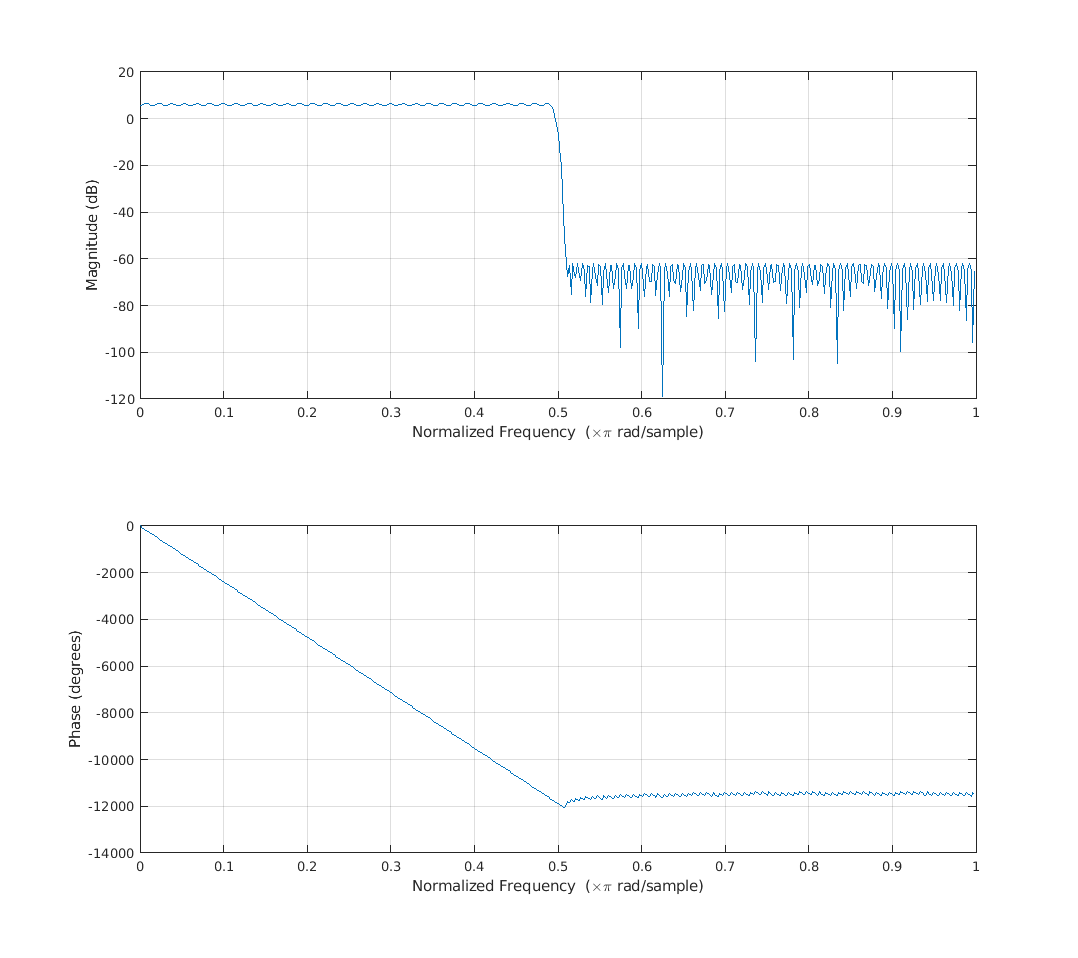

load("EqInterp.mat")
load("EqInterpCoeff.mat")

graph = figure;
freqz(EqInterpCoeff,1);
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

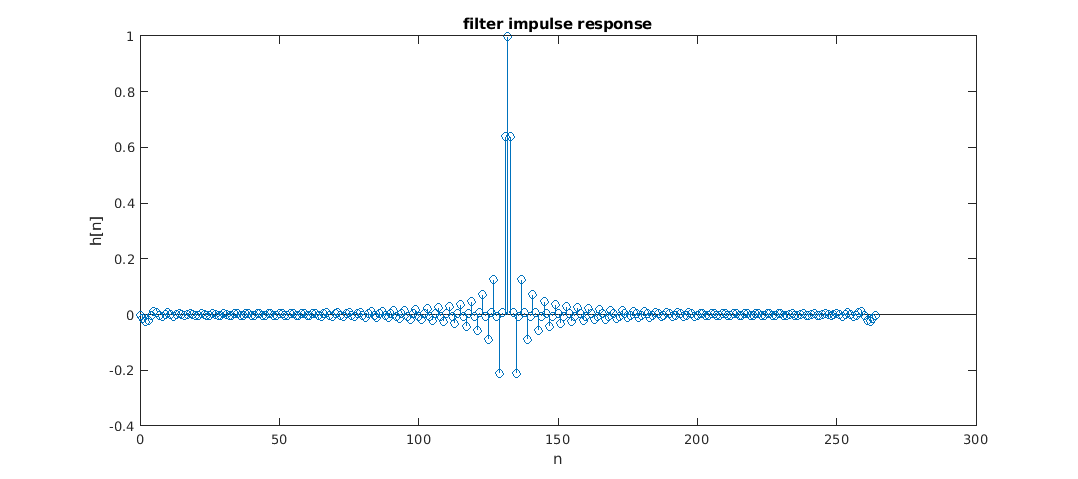

% graph filter impulse response
graph = figure;
stem(0:length(EqInterpCoeff)-1,EqInterpCoeff)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

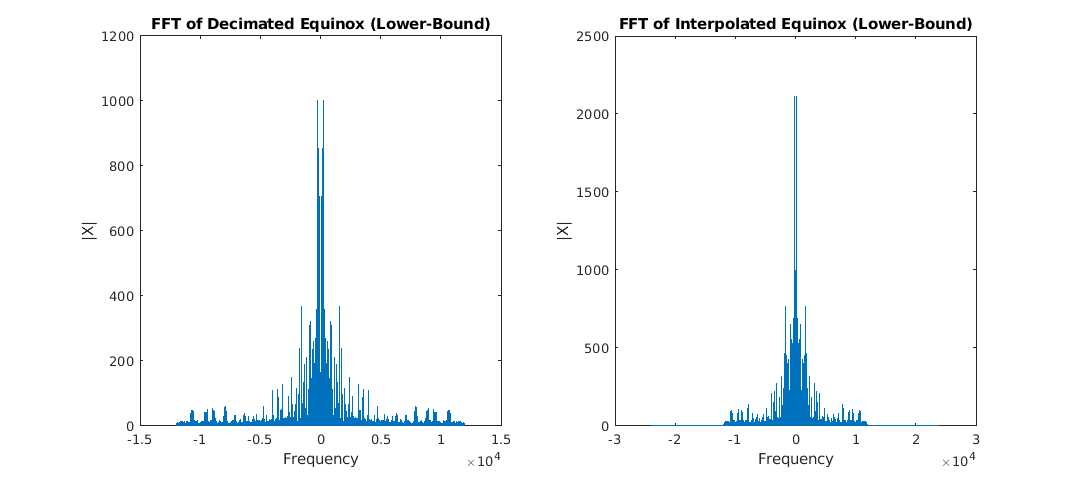

interpolatedEquinox_2 = filter(EqInterp, upsampledEquinox_2);

interpolatedEquinoxFFT_2 = abs(fftshift(fft(interpolatedEquinox_2)));   % Zero-Centered FFT
interpolatedEquinoxF_2 = (-length(interpolatedEquinox_2)/2:...
    length(interpolatedEquinox_2)/2-1)/length(interpolatedEquinox_2)...
    *decimatedEquinoxInfo_2.SampleRate*L;                               % Zero-Centered Frequency Range 

graph = figure;
subplot(121)
plot(decimatedEquinoxF_2, decimatedEquinoxFFT_2)
title('FFT of Decimated Equinox (Lower-Bound)');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,2)
plot(interpolatedEquinoxF_2, interpolatedEquinoxFFT_2)
title('FFT of Interpolated Equinox (Lower-Bound)');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

#### Upper-band File

decimatedEquinoxInfo_3

decimatedEquinoxInfo_3 = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/decimatedEquinox_3.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 24000
         TotalSamples: 359983
             Duration: 14.9993
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


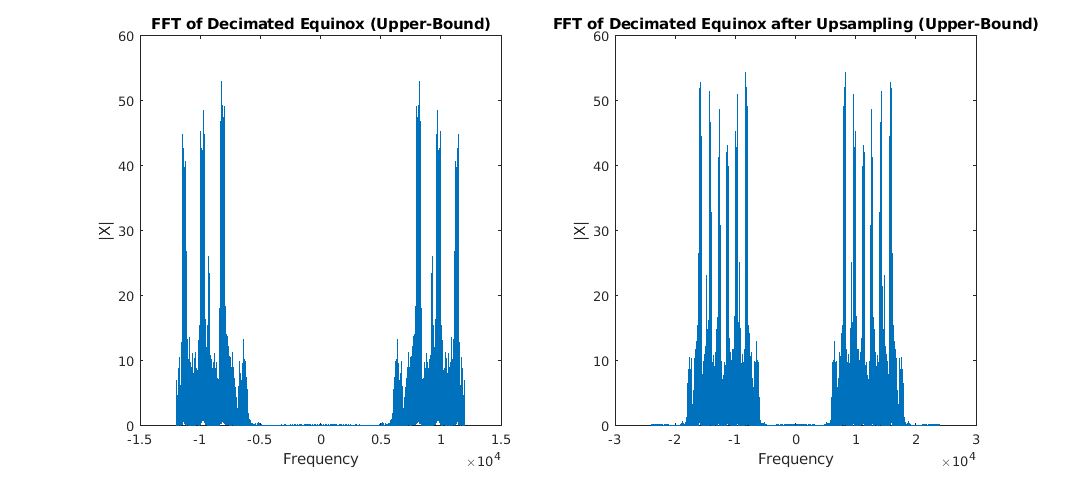

L = 48000/decimatedEquinoxInfo_3.SampleRate;

upsampledEquinox_3(1:L:L*decimatedEquinoxInfo_3.TotalSamples) = decimatedEquinox_3;

upsampledEquinoxFFT_3 = abs(fftshift(fft(upsampledEquinox_3)));     % Zero-Centered FFT
upsampledEquinoxF_3 = (-length(upsampledEquinox_3)/2:...
    length(upsampledEquinox_3)/2-1)/length(upsampledEquinox_3)...
    *decimatedEquinoxInfo_3.SampleRate*L;                           % Zero-Centered Frequency Range 

graph = figure;
subplot(121)
plot(decimatedEquinoxF_3, decimatedEquinoxFFT_3)
title('FFT of Decimated Equinox (Upper-Bound)');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,2)
plot(upsampledEquinoxF_3, upsampledEquinoxFFT_3)
title('FFT of Decimated Equinox after Upsampling (Upper-Bound)');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

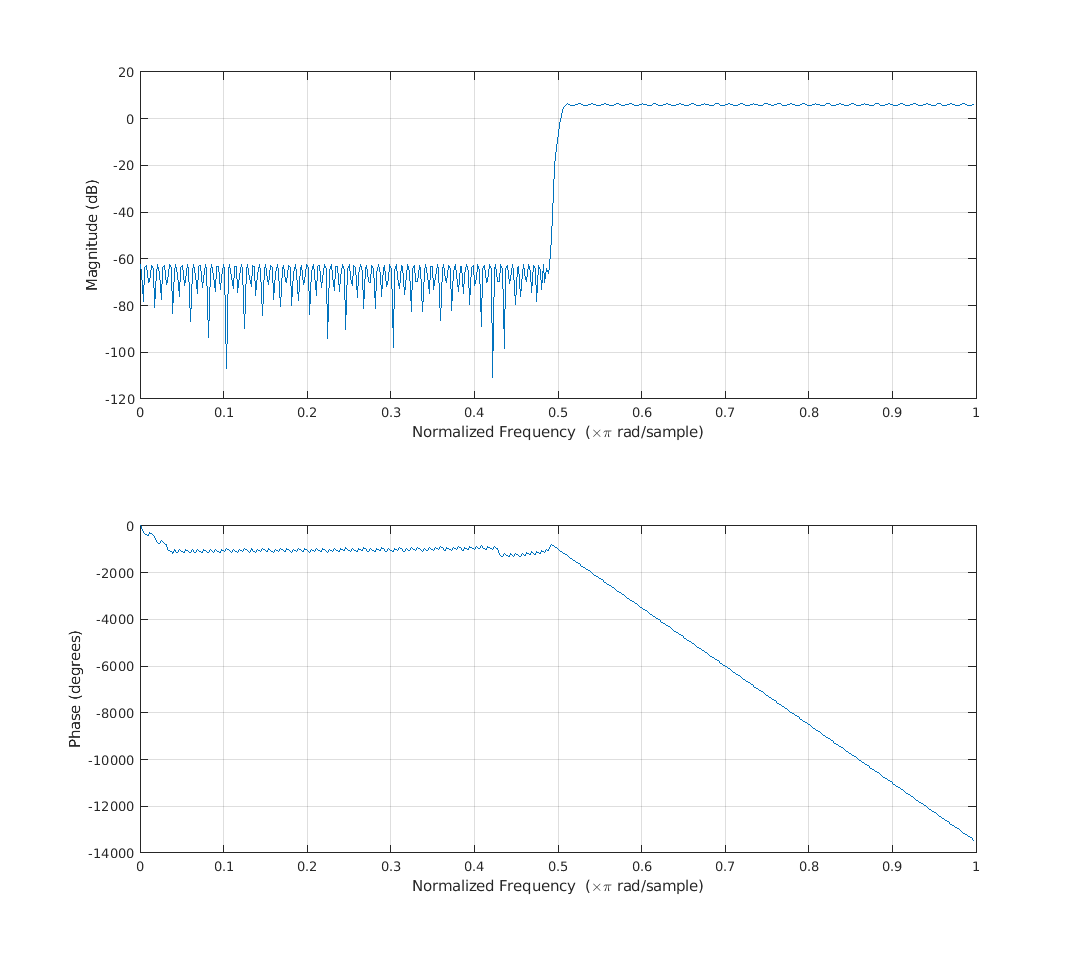

load("EqInterp2.mat")
load("EqInterpCoeff2.mat")

graph = figure;
freqz(EqInterpCoeff2,1);
set(graph,'Units','normalized','Position',[0 0 1 0.5]);

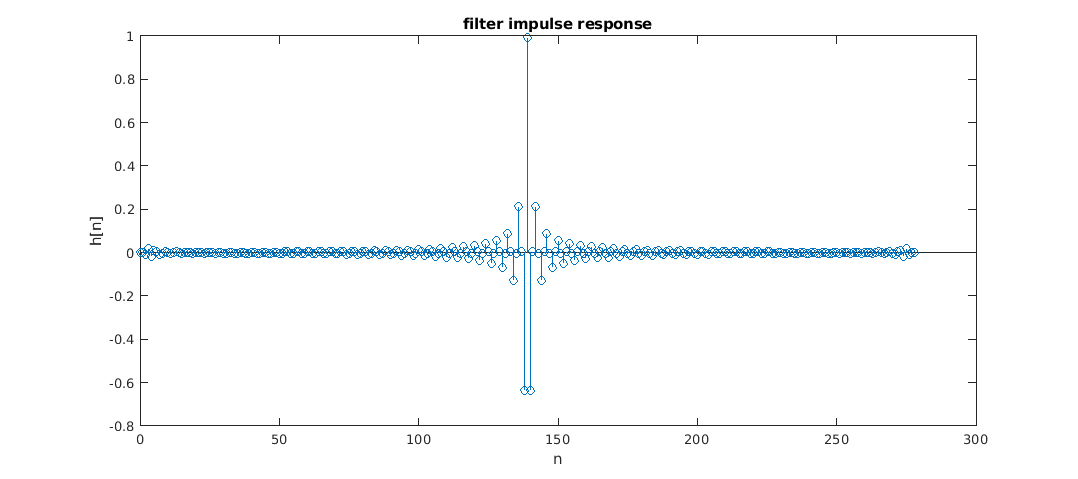

% graph filter impulse response
graph = figure;
stem(0:length(EqInterpCoeff2)-1,EqInterpCoeff2)
xlabel('n')
ylabel('h[n]')
title('filter impulse response')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

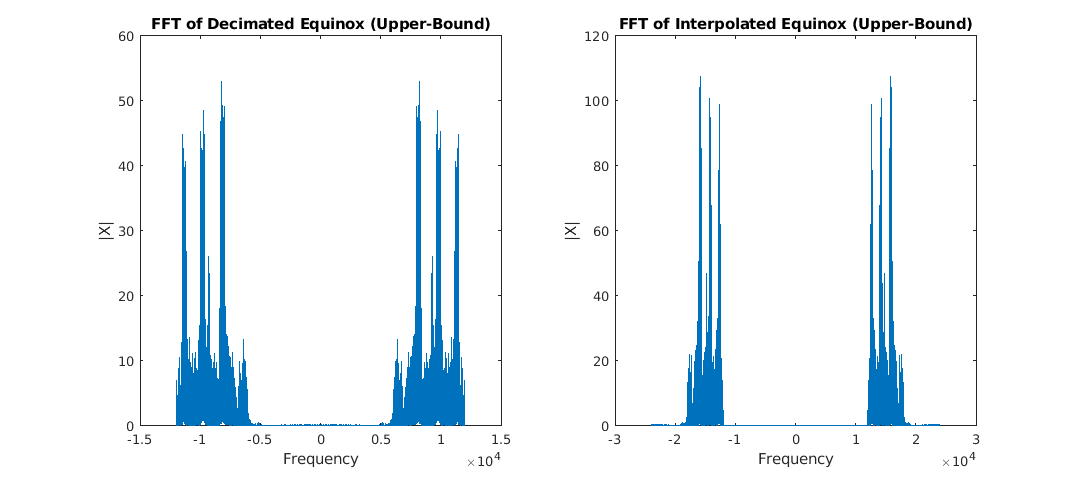

interpolatedEquinox_3 = filter(EqInterp2, upsampledEquinox_3);

interpolatedEquinoxFFT_3 = abs(fftshift(fft(interpolatedEquinox_3)));   % Zero-Centered FFT
interpolatedEquinoxF_3 = (-length(interpolatedEquinox_3)/2:...
    length(interpolatedEquinox_3)/2-1)/length(interpolatedEquinox_3)...
    *decimatedEquinoxInfo_3.SampleRate*L;                               % Zero-Centered Frequency Range 

graph = figure;
subplot(121)
plot(decimatedEquinoxF_3, decimatedEquinoxFFT_3)
title('FFT of Decimated Equinox (Upper-Bound)');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,2)
plot(interpolatedEquinoxF_3, interpolatedEquinoxFFT_3)
title('FFT of Interpolated Equinox (Upper-Bound)');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

#### Combining the Lower-band and Upper-band file

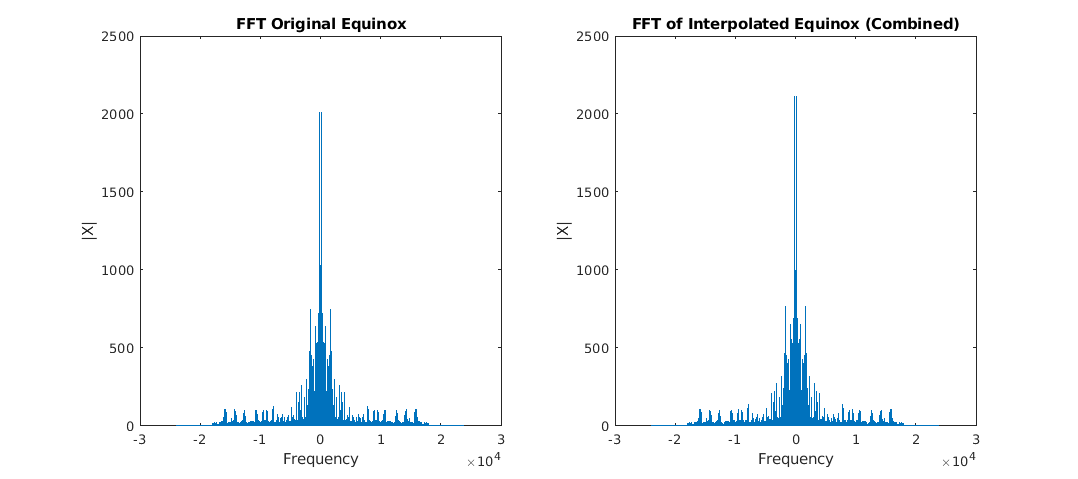

interpolatedEquinox_Combined = interpolatedEquinox_2 + interpolatedEquinox_3;

audiowrite("interpolatedEquinox_Combined.wav", interpolatedEquinox_Combined, 48000);

interpolatedEquinoxFFT_Combined = abs(fftshift(fft(interpolatedEquinox_Combined)));     % Zero-Centered FFT
interpolatedEquinoxF_Combined = (-length(interpolatedEquinox_Combined)/2:...
    length(interpolatedEquinox_Combined)/2-1)/length(interpolatedEquinox_Combined)...
    *decimatedEquinoxInfo_3.SampleRate*L;                                               % Zero-Centered Frequency Range 

graph = figure;
subplot(121)            
plot(equinoxF, equinoxFFT)
title('FFT Original Equinox');
ylabel('|X|')
xlabel('Frequency');
subplot(1,2,2)
plot(interpolatedEquinoxF_Combined, interpolatedEquinoxFFT_Combined)
title('FFT of Interpolated Equinox (Combined)');
ylabel('|X|')
xlabel('Frequency');
set(graph,'Units','normalized','Position',[0 0 1 0.25]);

interpolatedEquinox_Combined_Info = audioinfo("interpolatedEquinox_Combined.wav")

interpolatedEquinox_Combined_Info = struct with fields:
             Filename: '/var/Programs/GitHub/Digital-Signal-Processing/Homework6/interpolatedEquinox_Combined.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 719965
             Duration: 14.9993
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


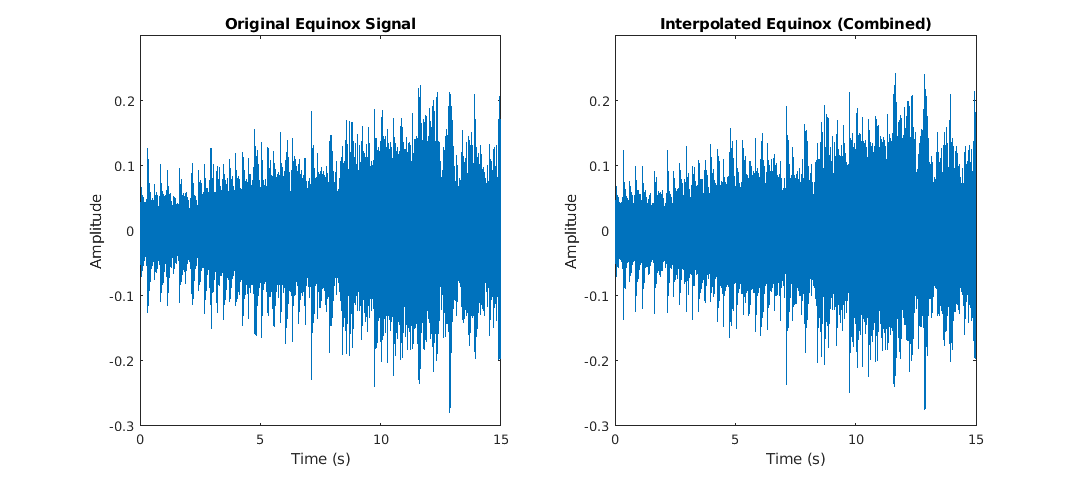

timeInterpolatedEquinox_Combined = linspace(0, interpolatedEquinox_Combined_Info.Duration,...
    interpolatedEquinox_Combined_Info.TotalSamples);

graph = figure;
subplot(121)
plot(timeEquinox, equinox)
title('Original Equinox Signal')
ylabel('Amplitude')
xlabel('Time (s)')
ylim([-0.3 0.3])   

subplot(122)
plot(timeInterpolatedEquinox_Combined, interpolatedEquinox_Combined)
title('Interpolated Equinox (Combined)')
ylabel('Amplitude')
xlabel('Time (s)')
set(graph,'Units','normalized','Position',[0 0 1 0.25]);
ylim([-0.3 0.3])

*After an visual and auditory inspection I couldn't tell any difference between the two signals, both in frequnecy domain and time domain.*

*I don't hear any degradation in the audio quality or any loss in the spectrum.*

*But to make sure, lets look at the ****Mean-Absolute Error ****between the two signals:*

% Adjusting for the delay
Error = equinox(350:end-350) - interpolatedEquinox_Combined(350:end-350)';

mae(Error)

ans = 0.0447

*As you can see we have very little MAE of 4.47%.*